# **Handling ADCIRC in MATLAB**

## Setup

This is the first of several MATLAB Live Scripts that demonstrate the basics of how to visualize and analyze ADCIRC output in MATLAB.

The first step is to load the needed external toolboxes that handle netCDF files in general (nctoolbox) and ADCIRC-specific tools (adcirc_util).  Both are available via GitHub:

- `nctoolbox   - `[`https://github.com/nctoolbox/nctoolbox.git`](https://github.com/nctoolbox/nctoolbox.git)

- `adcirc_util - `[`https://github.com/BrianOBlanton/adcirc_util.git`](https://github.com/BrianOBlanton/adcirc_util.git)

Clone these repos and then add the paths to your MATLAB path.  In this demo, I've checked out the repos to some directory called GitHubDirectory.  I keep all GH repos in one location, called Github, in my home directory.  You will need to set these according to how you decide to maintain GH repos. 

To clone a GH repository, do this in a shell, NOT in MATLAB.

- Make a main directory to hold GH repos, adjusting according to your environment:

                     `mkdir /home/<MyUserName>/GitHub`

- Cd to the GitHub directory

- Clone the adcirc_util repo:

                   ` git clone `[`https://github.com/BrianOBlanton/adcirc_util.git`](https://github.com/BrianOBlanton/adcirc_util.git)

- This will download the main repo and put it into a directory called adcirc_util.

- Clone the nctoolbox repo:

                      `git clone `[`https://github.com/nctoolbox/nctoolbox.git`](https://github.com/nctoolbox/nctoolbox.git)

Then, in MATLAB, changing the details below to match what you did above,

% define setup_nctoolbox
HOME=getenv('HOME');
GitHubDirectory=[HOME '/GitHub/'];

% add nctoolbox
addpath([GitHubDirectory '/nctoolbox'])
setup_nctoolbox

NCTOOLBOX added to Matlab path



% add adcirc_util toolbox
ADCIRC=[GitHubDirectory '/BrianOBlanton/adcirc_util'];
addpath(ADCIRC)
AddAdcircPaths(ADCIRC)

## Opening a netCDF file

Nctoolbox is very useful for dealing with netCDF and grib output in MATLAB.   Since ADCIRC can output netCDF files with CF-UGRID metadata, nctoolbox becomes almost essential.  Here's how to open a netCDF file that livees on a THREDDS server.

url='http://tds.renci.org:8080/thredds/dodsC/tc/florence/00/nc_inundation_v9.99_w_rivers/pod.penguincomputing.com/OwiHindcast/hindcast/maxele.63.nc';
nc=ncgeodataset(url)

nc =   ncgeodataset with properties:

     location: 'http://tds.renci.org:8080/thredds/dodsC/tc/florence/00/nc_inundation_v9.99_w_rivers/pod.penguincomputing.com/OwiHindcast/hindcast/maxele.63.nc'
       netcdf: [1×1 ucar.nc2.dataset.NetcdfDataset]
    variables: {18×1 cell}

Note that nc is an nctoolbox/ncgeodataset object with (in this case) 18 variables attached to it.  Only the netCDF file metadata has been downloaded to MATLAB, not actual ADCIRC data (yet).  This is called lazy-loading and is what makes nctoolbox great.  The lazy-loading is provided by the underlying java netCDF class.  

Each ADCIRC netCDF actually contains the ADCIRD grid data that the solution was computed with.  While that may seem redundant and wasteful (in a disk space sense), this substantially simplifies life because we never have to ask, "which grid was this output computed on?".  In fact, this is part of the CF-UGRID specification.  

## Extracting data

So, to retrieve the ADCIRC grid from the nc object: 

tic
TheGrid=ExtractGrid(nc)

TheGrid = struct with fields:
              name: 'nc_inundation_v9.99_w_rivers'
                 e: [1234231×3 double]
                 x: [624782×1 double]
                 y: [624782×1 double]
                 z: [624782×1 double]
               bnd: [15627×2 double]
           ar_cart: [1234231×1 double]
            A_cart: [1234231×3 double]
           A0_cart: [1234231×2 double]
            B_cart: [1234231×3 double]
            T_cart: [1234231×3 double]
           dx_cart: [1234231×3 double]
           dy_cart: [1234231×3 double]
           dl_cart: [1234231×1 double]
    interiorangles: [1234231×3 double]
             acute: [1234231×1 logical]
                ar: [1234231×1 double]
              ineg: [0×1 double]
                EL: [1234231×3 double]
                dl: [1234231×1 double]
           triQual: [1234231×1 double]
                 A: [1234231×3 double]
                 B: [1234231×3 double]
                A0: [1234231×2 double]
                 T: [1234231×3 d

toc

Elapsed time is 5.667181 seconds.


Notice in the panel to the right that the variable TheGrid is a MATLAB struct containing the various parts of the ADCIRC grid (e,x,y,z) extracted from the file at the endpoint of the url, as well as some fields that are computed by ExtractGrid (e.g., ar_cart).  The reason it a few seconds (~5) is because the data had to be fetched from the file, which in this case lives on a server, not on the desktop.  Techncally, the ExtractGrid function is doing things inside that get the data out of the nc object.  We'll see exactly what a bit later. 

## Plotting the ADCIRC grid

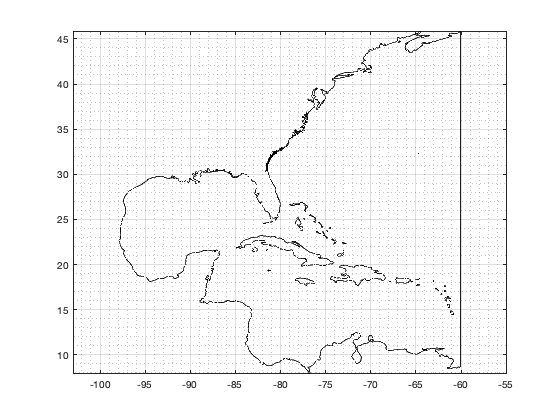

figure
plotbnd(TheGrid)
axis('equal')
grid on
grid minor
set(gca,'box','on')

## Add a depth contour

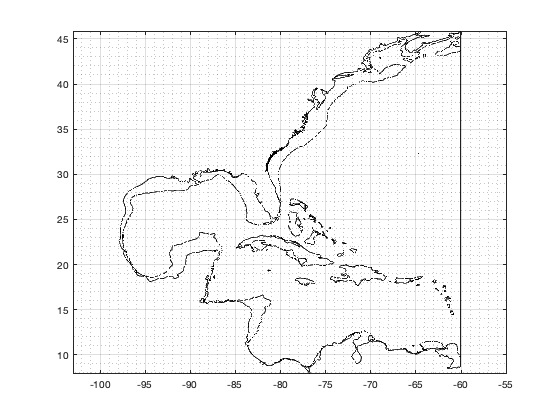

hc=lcontour(TheGrid,TheGrid.z,100,'Color','k');

## Extract data from the nc object and plot

Let's make a plot of the maximum water level.  The ADCIRC netCDF file variable name for water level is "zeta", and for the *maximum water level*, it is "zeta_max".  We can use this variable name to get to the data: 

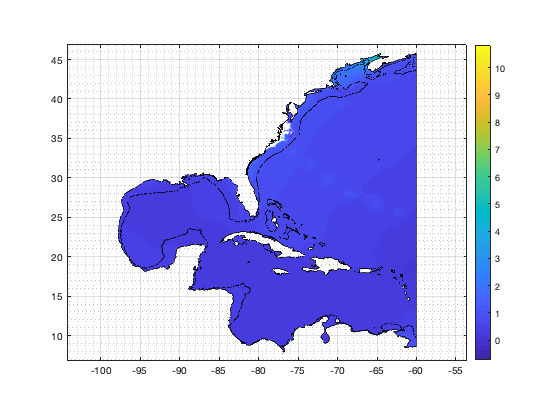

%zetamax=nc.data('zeta_max');
% alternatively:
zetamax=nc{'zeta_max'}(:);  
colormesh2d(TheGrid,zetamax)
colorbar

#### Let's adjust the plot a bit to better see what's going on.

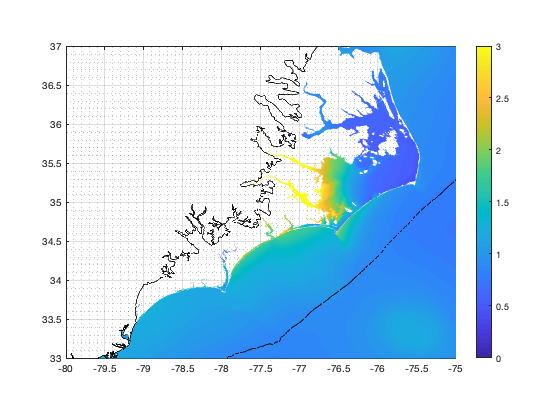

% set color limits
caxis([0 3])
% zoom in
axis([-80 -75 33 37])

## Interpolating into the solution

Now, suppose I wanted to know what the water level is at an arbitrary point in the grid, at (e.g.) lon=-76.5, lat=35.0.

lon=-76.5;
lat=35.0;

1) We first need to know what element the point is in:

j=findelem(TheGrid,[lon lat]); 

j =       753914

So, the point is in element # 753914.  Let's "confirm" that.

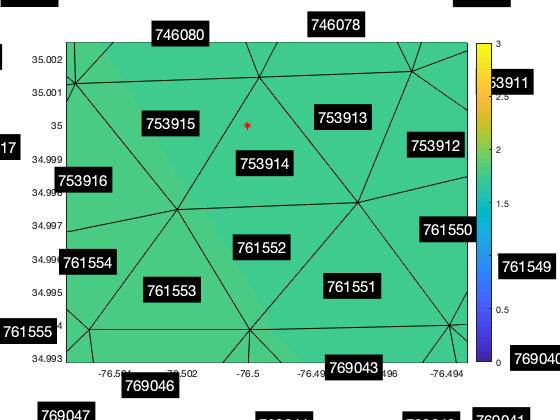

line(lon,lat,'Marker','*','Color','r')
xlim([-76.50543 -76.49341])
ylim([34.99287 35.00250])
drawelems(TheGrid);
numelems(TheGrid)

Yep.  that's it. 

2) Interpolate the zetamax field to this location

z_i=interp_scalar(TheGrid,zetamax,lon,lat,j)

z_i =      1.765179160583585e+00

So, the water level at this location is 1.765 m.   

Technically, you do not need to pre-compute the element(s) containing the point(s).  You could just call interp_scalar immediately:

z_i=interp_scalar(TheGrid,zetamax,lon,lat)

Computing elements within interp_scalar.


z_i =      1.765179160583585e+00

However, if there are many points at which to interpolate, then computing the elements for every call to interp_scalar becomes more expensive than the interpolation.  So it's a good habit to pre-compute elements when possible.  

If there are ***A LOT ***of points, like 10K+, then it's best to use a different element finding approach.  The following demonstrates using an STR tree.

1) Compute the strtree and store it in the grid struct.  For a large grid, this can take a bit of time, but if you are interpolating a lot of points, then the cost is comparatively low.  

TheGrid.strtree=ComputeStrTree(TheGrid);

Computing STRtree for 1234231 elements ... 
STRtree for 1234231 elements computed in 70.8 secs


Note that the STR tree takes about 1 minute for a grid with 1.2M elements.  

Now, compute the elements containing the same point, but with the strtree:

j=FindElementsInStrTree(TheGrid,lon,lat)

j =       753914

 Good. Same element as previous.